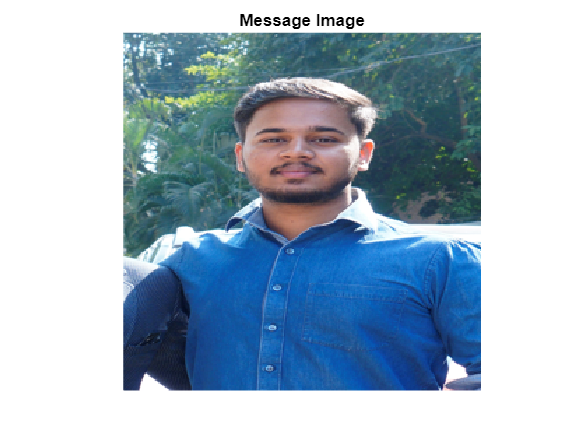

msg = imread('vivek.jpg');
cvr = imread('image.jpg');
msg = imresize(msg,[256 256]);
cvr = imresize(cvr,[256 256]);

figure
imshow(msg);
title('Message Image');

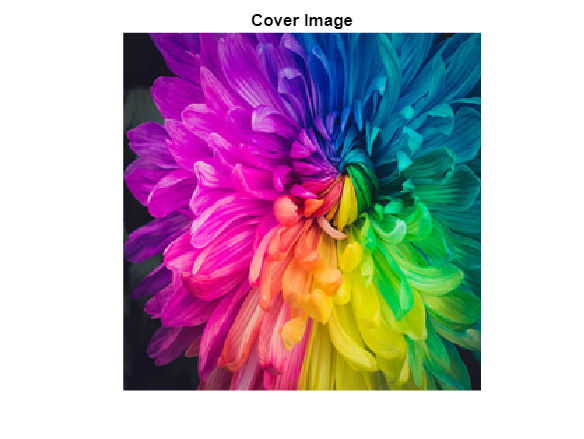


figure
imshow(cvr);
title('Cover Image');

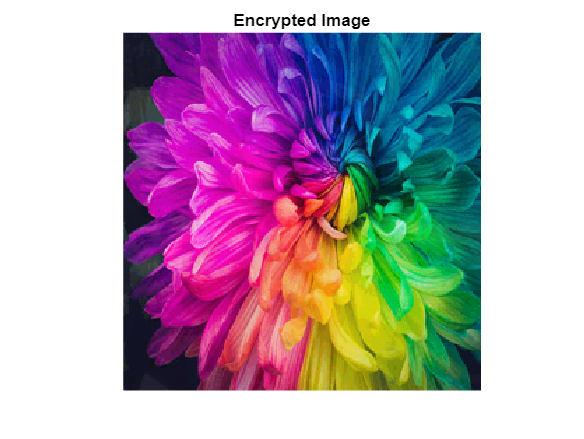


[r, c, p]=size(msg);
for i=1:p
    for j=1:r
        for k=1:c
            rm = dec2bin(msg(j, k, i), 8);
            rc = dec2bin(cvr(j, k, i), 8);
            st = strcat(rc(1:4), rm(1:4));
            stimg(j, k, i) = bin2dec(st);
        end
    end
end

figure
imshow(uint8(stimg));
title('Encrypted Image');

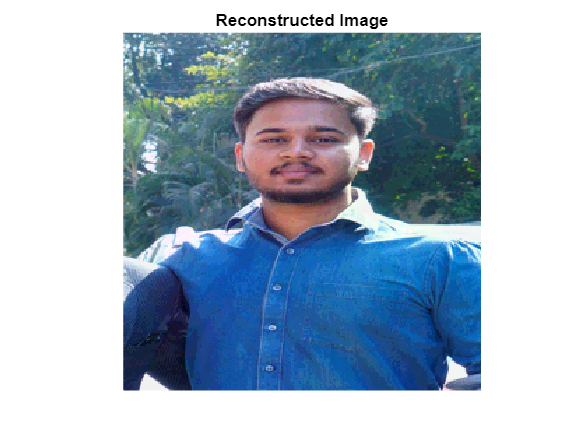

imwrite(uint8(stimg), 'encrypted.png', 'png');

a = imread('encrypted.png');
a = imresize(a, [256 256]);
[r, c, p]=size(a);
for i = 1:r
    for j = 1:c
        for k = 1 : p
            d = dec2bin(a(i, j, k), 8);
            f = strcat(d(5:8), d(1:4));
            recimg(i, j, k) = bin2dec(f);
        end
    end
end

figure
imshow(uint8(recimg));
title('Reconstructed Image');


imwrite(uint8(recimg),'steg.png','png');